clc; clear; close all;
% 如需运行，记得多试几次，有概率在一开始就报错
% 遗传算法参数
nVar = 8;
lb = [70, 0, 0, 0, 1, 0, 1, 0]; % 下限
ub = [140, 2*pi, 10, 15, 10, 15, 10, 15]; % 上限
popSize = 300; % 种群内，个体数量
maxGen = 300; % 迭代次数
pc = 0.8; % 交叉概率
pm = 0.3; % 变异概率
etaC = 20;  % 交叉分布指数
etaM = 20; % 变异分布指数

% 初始化种群参数
% 创建nVar维的哈尔顿序列集合，通过大规模覆盖可行域，保证初始解能接近最优解
p = haltonset(nVar, 'Skip', 1); % 'Skip'=1 跳过首个可能偏差较大的点
% 生成popSize个在[0, 1]区间均匀分布的拟随机点
qrs_points = net(p, popSize);

% 将拟随机点缩放至搜索空间边界范围内
pop = lb + qrs_points .* (ub - lb);

fit = evalPopulation(pop); % 计算适应度即最大有效遮蔽时长
[bestf,bestIdx] = max(fit);
bestX_ga = pop(bestIdx, :); % 记录遗传算法初始最优解
trace = zeros(maxGen, 2); % 绘制收敛曲线

fprintf('初始最佳遮蔽时间 = %.2f 秒\n', bestf);

初始最佳遮蔽时间 = -0.01 秒


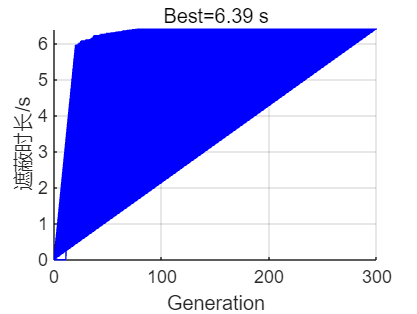

Gen  20  best=5.94 s  x=[71.87 0.17 -0.06 0.01 1.19 0.19 4.79 1.95]
Gen  40  best=6.21 s  x=[91.61 0.15 0.00 0.16 1.07 0.06 5.05 1.90]
Gen  60  best=6.31 s  x=[98.45 0.15 0.00 0.04 1.06 -0.00 5.63 0.86]
Gen  80  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 100  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 120  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 140  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 160  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 180  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 200  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 220  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 240  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 260  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 280  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.00 0.00 5.21 2.01]
Gen 300  best=6.39 s  x=[104.33 0.15 0.00 0.00 1.


% 遗传算法主循环
figure('Name','收敛曲线'); hold on; grid on;
bestX = zeros(1, length(lb));
for gen = 1:maxGen
    matingPool = TournamentSelect(pop, fit,popSize); % 竞争
    offspring  = GeneticOp(matingPool, pc, pm, etaC, etaM, lb, ub); % 遗传操作（传入边界）
    offFit = evalPopulation(offspring);    % 计算子代适应度
    % 合并+精英截断
    [~, eliteI] = max(fit);
    newPop = [pop; offspring];
    newFit = [fit; offFit];
    [sortedF, sortedI] = sort(newFit, 'descend');
    newPop = newPop(sortedI(1:popSize), :);
    newFit = sortedF(1:popSize);
    newPop(1,:) = pop(eliteI, :); 
    newFit(1) = fit(eliteI);
    pop = newPop;
    fit = newFit;
    % 更新最优
    [curBest,curI] = max(fit);
    if curBest > bestf
        bestf = curBest;
        bestX = pop(curI, :);
    end
    trace(gen,:) = [gen bestf];
    if mod(gen,20) == 0 || gen == maxGen
        fprintf('Gen %3d  best=%.2f s  x=[%.2f %.2f %.2f %.2f %.2f %.2f %.2f %.2f]\n',...
                 gen, bestf, bestX);
    end
    plot(trace(:,1), trace(:,2), 'b-');
    xlabel('Generation');
    ylabel('遮蔽时长/s');
    title(sprintf('Best=%.2f s', bestf));
    drawnow;
end

% 输出最优解
fprintf('最优遮蔽时长=%.2f s\n', bestf);

最优遮蔽时长=6.39 s


 fprintf('最优变量  vx=%.2f  vy=%.2f  t_uav_1=%.2f  t_descend_1=%.2f t_delta_2=%.2f  t_descend_2=%.2f t_delta_3=%.2f  t_descend_3=%.2f\n', bestX);

最优变量  vx=104.33  vy=0.15  t_uav_1=0.00  t_descend_1=0.00 t_delta_2=1.00  t_descend_2=0.00 t_delta_3=5.21  t_descend_3=2.01
